# **Truss example code **

## J.Morlier MAE2017

A 6 bar truss is loaded by 2 external forces.

Use FE to solve the problem

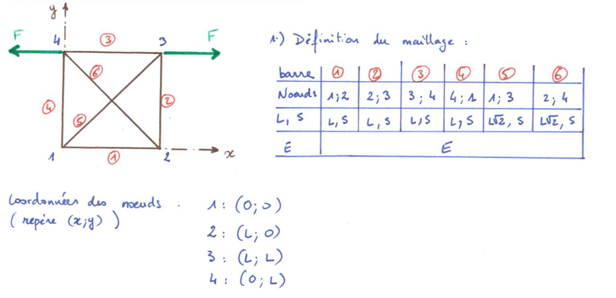



clear all; close all;
    



%%%%%%%%%%%%%%%%%%%%%
%PREPROCESSING
%%%%%%%%%%%%%%%%%%%%%
E=1;%Mpa
S=1;%m*m
L=1;%m

%constant =1
const=E*S/L;

%Connectivity diagram
IEN =  [1 2 3 4 1 4; 2 3 4 1 3 2];  
 
%BCs u1=v1=v2=0
free=[3 5 6 7 8];

%prescribed force at DOFs
f=[0 10 0 -10 0]

f =      0    10     0   -10     0




%p is the angle define by global  axis X

ndof=2; %DOF per node
nel=6; %Number of bar elements
nen=2;% Number of Node per elements

%Try to describe the topology
phi   	= [0 90 0 90 45 135 ];   	% Angle


%%%%%%%%%%%%%%%%%%%%%
%COMPUTING...
%%%%%%%%%%%%%%%%%%%%%

%K elementary matrix precomputing
for k=1:nel
    
p = phi(k)*pi/180;       % converts degrees to radians
    s   = sin(p);        c  = cos(p);
    s2  = s^2;           c2 = c^2;
       if k==5 % bar 5&6 lenght L*sqrt(2)
               const=const/sqrt(2);
           end

ke(:,:,k) = const*[c2      c*s    -c2     -c*s;       % stiffness matrix for 2D
                c*s     s2     -c*s     -s2; 
               -c2     -c*s     c2       c*s;
               -c*s    -s2      c*s      s2];
          
end


 
%in 2D 4 DOF !
K=zeros(nen*4,nen*4)

K =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


m1 =      1     0    -1     0
     0     0     0     0
    -1     0     1     0
     0     0     0     0


K =      1     0    -1     0     0     0     0     0
     0     0     0     0     0     0     0     0
    -1     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


m1 =      1     0    -1     0
     0     0     0     0
    -1     0     1     0
     0     0     0     0


m1 =     0.0000    0.0000   -0.0000   -0.0000
    0.0000    1.0000   -0.0000   -1.0000
   -0.0000   -0.0000    0.0000    0.0000
   -0.0000   -1.0000    0.0000    1.0000


K =      1     0    -1     0     0     0     0     0
     0     0     0     0     0     0     0     0
    -1     0     1     0     0     0     0     0
     0     0     0     1     0    -1     0     0
     0     0     0     0     0     0     0     0
     0     0     0    -1     0     1     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


m1 =      0     0     0     0
     0     1     0    -1
     0     0     0     0
     0    -1     0     1


m1 =      1     0    -1     0
     0     0     0     0
    -1     0     1     0
     0     0     0     0


K =      1     0    -1     0     0     0     0     0
     0     0     0     0     0     0     0     0
    -1     0     1     0     0     0     0     0
     0     0     0     1     0    -1     0     0
     0     0     0     0     1     0    -1     0
     0     0     0    -1     0     1     0     0
     0     0     0     0    -1     0     1     0
     0     0     0     0     0     0     0     0


m1 =      1     0    -1     0
     0     0     0     0
    -1     0     1     0
     0     0     0     0


m1 =     0.0000    0.0000   -0.0000   -0.0000
    0.0000    1.0000   -0.0000   -1.0000
   -0.0000   -0.0000    0.0000    0.0000
   -0.0000   -1.0000    0.0000    1.0000


K =      1     0    -1     0     0     0     0     0
     0     1     0     0     0     0     0    -1
    -1     0     1     0     0     0     0     0
     0     0     0     1     0    -1     0     0
     0     0     0     0     1     0    -1     0
     0     0     0    -1     0     1     0     0
     0     0     0     0    -1     0     1     0
     0    -1     0     0     0     0     0     1


m1 =      0     0     0     0
     0     1     0    -1
     0     0     0     0
     0    -1     0     1


m1 =     0.3536    0.3536   -0.3536   -0.3536
    0.3536    0.3536   -0.3536   -0.3536
   -0.3536   -0.3536    0.3536    0.3536
   -0.3536   -0.3536    0.3536    0.3536


K =     1.3536    0.3536   -1.0000         0   -0.3536   -0.3536         0         0
    0.3536    1.3536         0         0   -0.3536   -0.3536         0   -1.0000
   -1.0000         0    1.0000         0         0         0         0         0
         0         0         0    1.0000         0   -1.0000         0         0
   -0.3536   -0.3536         0         0    1.3536    0.3536   -1.0000         0
   -0.3536   -0.3536         0   -1.0000    0.3536    1.3536         0         0
         0         0         0         0   -1.0000         0    1.0000         0
         0   -1.0000         0         0         0         0         0    1.0000


m1 =     0.3536    0.3536   -0.3536   -0.3536
    0.3536    0.3536   -0.3536   -0.3536
   -0.3536   -0.3536    0.3536    0.3536
   -0.3536   -0.3536    0.3536    0.3536


m1 =     0.3536   -0.3536   -0.3536    0.3536
   -0.3536    0.3536    0.3536   -0.3536
   -0.3536    0.3536    0.3536   -0.3536
    0.3536   -0.3536   -0.3536    0.3536


K =     1.3536    0.3536   -1.0000         0   -0.3536   -0.3536         0         0
    0.3536    1.3536         0         0   -0.3536   -0.3536         0   -1.0000
   -1.0000         0    1.3536   -0.3536         0         0   -0.3536    0.3536
         0         0   -0.3536    1.3536         0   -1.0000    0.3536   -0.3536
   -0.3536   -0.3536         0         0    1.3536    0.3536   -1.0000         0
   -0.3536   -0.3536         0   -1.0000    0.3536    1.3536         0         0
         0         0   -0.3536    0.3536   -1.0000         0    1.3536   -0.3536
         0   -1.0000    0.3536   -0.3536         0         0   -0.3536    1.3536


m1 =     0.3536   -0.3536   -0.3536    0.3536
   -0.3536    0.3536    0.3536   -0.3536
   -0.3536    0.3536    0.3536   -0.3536
    0.3536   -0.3536   -0.3536    0.3536


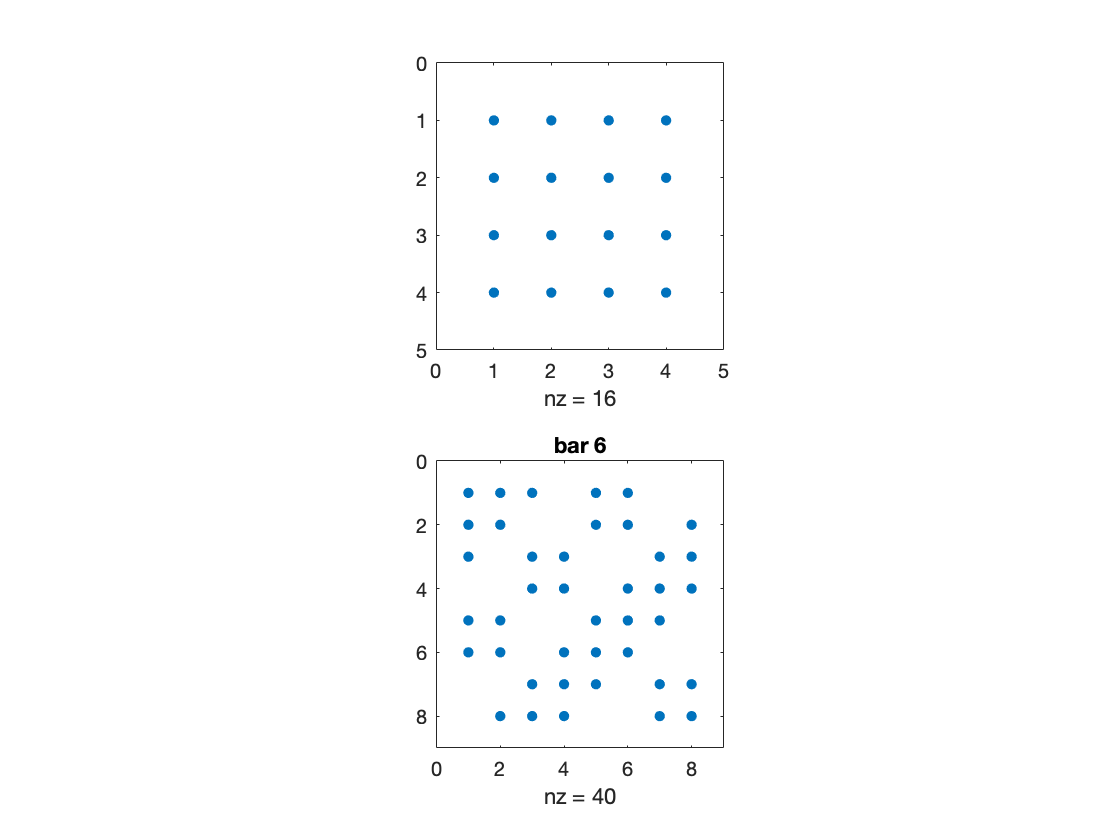


%Assembly of K
for i=1:length(IEN)
    j=IEN(1,i);
    k=IEN(2,i);
    %debugg
%     h=(k-j);
%     if h==1
    m1=squeeze(ke(:,:,i))
%       2*j-1:2*j
%       2*k-1:2*k
K(2*j-1:2*j,2*k-1:2*k) = K(2*j-1:2*j,2*k-1:2*k) + m1(1:2,3:4);
K(2*j-1:2*j,2*j-1:2*j) = K(2*j-1:2*j,2*j-1:2*j) + m1(1:2,1:2);
K(2*k-1:2*k,2*k-1:2*k) = K(2*k-1:2*k,2*k-1:2*k) + m1(3:4,3:4);
K(2*k-1:2*k,2*j-1:2*j) = K(2*k-1:2*k,2*j-1:2*j) + m1(1:2,3:4);
%tolerance
   K(abs(K)<0.001)=0
   m1(abs(m1)<0.001)=0

   figure(1);subplot(211)
   spy(m1)
   subplot(212)
   spy(K); str=sprintf('bar %d',i);title(str);
   pause
%end

end

%determinant 
detK=det(K)

detK = -1.0381e-47




K=K(free,free);


%analytical response
A=[1+(sqrt(2)/4) 0 0 -sqrt(2)/4 sqrt(2)/4;0 1+(sqrt(2)/4) sqrt(2)/4 -1 0;...
    0 sqrt(2)/4  1+(sqrt(2)/4) 0 0; -(sqrt(2)/4) -1 0 1+(sqrt(2)/4) -(sqrt(2)/4);...
    (sqrt(2)/4) 0 0 -(sqrt(2)/4) 1+(sqrt(2)/4)];

% de=det(A)
    

%Inversion 
%K matrix sym DP
iA=inv(A)

iA =     0.8964    0.3964   -0.1036    0.5000   -0.1036
    0.3964    2.3107   -0.6036    1.9142    0.3964
   -0.1036   -0.6036    0.8964   -0.5000   -0.1036
    0.5000    1.9142   -0.5000    2.4142    0.5000
   -0.1036    0.3964   -0.1036    0.5000    0.8964


iK=inv(K)

iK =     0.8964    0.3964   -0.1036    0.5000   -0.1036
    0.3964    2.3107   -0.6036    1.9142    0.3964
   -0.1036   -0.6036    0.8964   -0.5000   -0.1036
    0.5000    1.9142   -0.5000    2.4142    0.5000
   -0.1036    0.3964   -0.1036    0.5000    0.8964




%Displacement Computation
U=iA*f'

U =    -1.0355
    3.9645
   -1.0355
   -5.0000
   -1.0355


Uk=iK*f'

Uk =    -1.0355
    3.9645
   -1.0355
   -5.0000
   -1.0355


%Displacement Computation analytical
UC=10*[ 0.25-(sqrt(2)/4) 0.75-(sqrt(2)/4) 0.25-(sqrt(2)/4) -0.5 0.25-(sqrt(2)/4)]'

UC =    -1.0355
    3.9645
   -1.0355
   -5.0000
   -1.0355


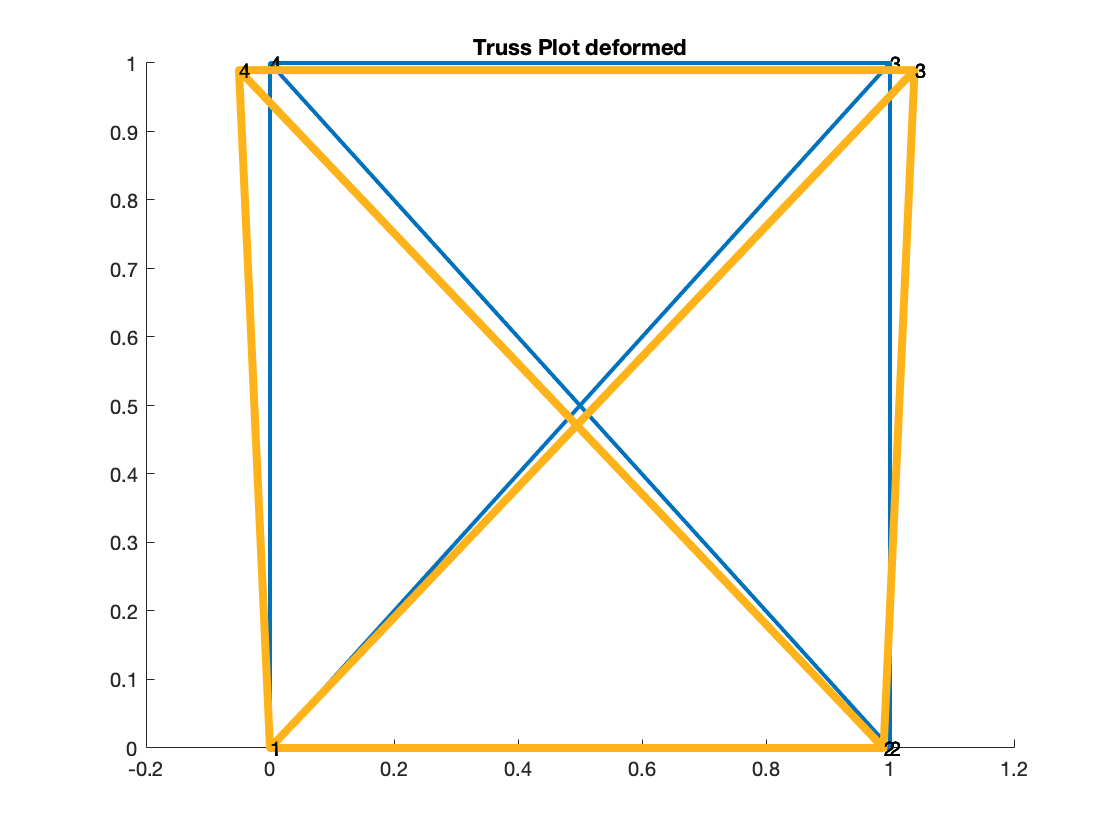



%%%%%%%%%%%%%%%%%%%%%
%PostProcessing
%%%%%%%%%%%%%%%%%%%%%
figure(2)

% Node:  1    2    3    4  5  6 (origin placed at node 1) 
%--------------------
x   =  [0.0  1.0  1.0  0 ];     % X coordinate  
y   =  [0.0  0.0  1.0  1 ];     % Y coordinate

d=[0 0 UC(1) 0 UC(2) UC(3) UC(4) UC(5)]';

    for i = 1:nel
        XX = [x(IEN(1,i)) x(IEN(2,i)) x(IEN(1,i)) ];
        YY = [y(IEN(1,i)) y(IEN(2,i)) y(IEN(1,i)) ];
        line(XX,YY,'LineWidth',2);hold on;
         
            text(XX(1),YY(1),sprintf('%0.5g',IEN(1,i)));
            text(XX(2),YY(2),sprintf('%0.5g',IEN(2,i)));
        
    end
    title('Truss Plot');
    
    
x=x+0.01*d(1:2:end)';
y=y+0.01*d(2:2:end)';
 
    for i = 1:nel
        XX = [x(IEN(1,i)) x(IEN(2,i)) x(IEN(1,i)) ];
        YY = [y(IEN(1,i)) y(IEN(2,i)) y(IEN(1,i)) ];
        figure(2);hold on;line(XX,YY,'LineWidth',4,'Color',[1 .7 .1]);hold on;
        
            text(XX(1),YY(1),sprintf('%0.5g',IEN(1,i)));
            text(XX(2),YY(2),sprintf('%0.5g',IEN(2,i)));
   
    end
    title('Truss Plot deformed');